close all
clear all

% qi = [xi, yi, theta_i]
qi =[0, 0, 0]'

qi =      0
     0
     0


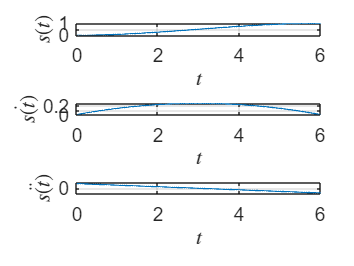

xi = qi(1);
yi = qi(2);
theta_i=qi(3);

qf = rand(1,3)';
qf = qf / norm(qf); % Normalize the random configuration
%qf=[0.819031913261206, 0.567041924552012, 0.087465312324590]
xf = qf(1);
yf = qf(2);
theta_f = qf(3);

k = 3;
Tf = 6;
Tc = 0.01;
Ti=0;
T=Tf-Ti;
t = 0:Tc:Tf;

[s, s_d, s_dd, a0, a1, a_2, a_3] = cubic(T, t);

figure
subplot(3,1,1)
plot(t,s,'LineWidth',1);
grid("on");
xlabel('$t$','Interpreter','latex')
ylabel('$s(t)$','Interpreter','latex')
set(gca,'Fontsize',14)

subplot(3,1,2)
plot(t,s_d,'LineWidth',1);
grid("on");
xlabel('$t$','Interpreter','latex')
ylabel('$\dot{s(t)}$','Interpreter','latex')
set(gca,'Fontsize',14)

subplot(3,1,3)
plot(t,s_dd,'LineWidth',1);
grid("on");
xlabel('$t$','Interpreter','latex')
ylabel('$\ddot{s(t)}$','Interpreter','latex')
set(gca,'Fontsize',14)

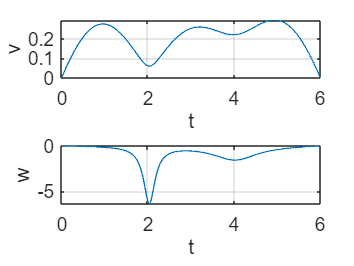

   
alpha_x = k*cos(theta_f)-3*xf;
alpha_y = k*sin(theta_f)-3*yf;
beta_x = k*cos(theta_i)+3*xi;
beta_y=  k*sin(theta_i)+3*yi;

[v_t, w_t, x_s, y_s , theta] = calcola_v_w_t(s, s_d, s_dd, qf, qi, alpha_x, alpha_y, beta_x, beta_y);

figure
% plot of the velocity 
subplot(2,1,1)
plot(t,v_t,'lineWidth',1)
xlabel('t')
ylabel('v')
set(gca,'Fontsize',14)
grid("on")
xlim([0, Tf])

hold on
subplot(2,1,2)
plot(t,w_t,'lineWidth',1)
xlabel('t')
ylabel('w')
set(gca,'Fontsize',14)
grid("on")
xlim([0, Tf])

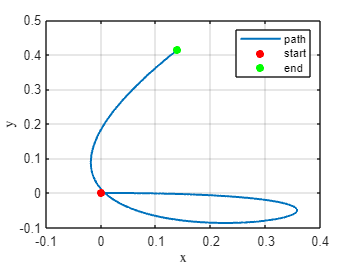


%"plot path"
figure
plot(x_s,y_s,'lineWidth',1.5)
xlabel('x','Interpreter','latex')
ylabel('y','Interpreter','latex')
hold on 
scatter(x_s(1),y_s(1),'red','filled','o')
hold on 
scatter(x_s(end),y_s(end),'green','filled','o')
grid("on");
legend('path','start','end' )

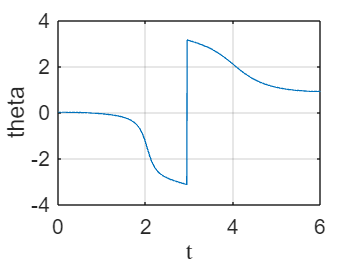


figure
plot(t,theta,'lineWidth',1)
xlabel('t','Interpreter','latex')
ylabel('theta')
set(gca,'Fontsize',16)
grid("on")

Velocity bounds are NOT satisfied.


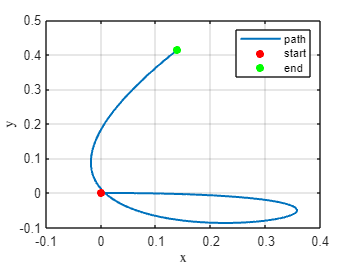

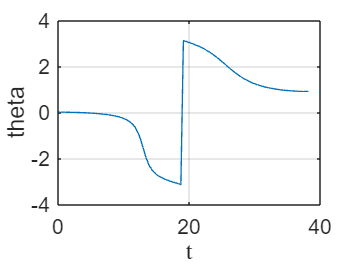

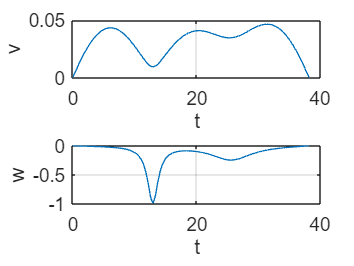


v_max = 2; 
w_max = 1;  

% Verifica se i limiti di velocità sono soddisfatti
if max(abs(v_t)) <= v_max && max(abs(w_t)) <= w_max
    disp('Velocity bounds are satisfied.')
    scaling=false;
else
    disp('Velocity bounds are NOT satisfied.')
    Tf=(Tf*max(max(abs(v_t))/2,max(abs(w_t))/1));
    t=0:Tc*Tf:Tf;
    T=Tf-0;
    [s, s_d, s_dd, a0, a1, a_2, a_3] = cubic(T, t);
    %[s,s_d,s_dd,pp] = cubicpolytraj([0 1],[0 Tf],t);
    [v_t, w_t, x_s, y_s , theta] = calcola_v_w_t(s, s_d, s_dd, qf, qi, alpha_x, alpha_y, beta_x, beta_y);


%"plot path"
figure
plot(x_s,y_s,'lineWidth',1.5)
xlabel('x','Interpreter','latex')
ylabel('y','Interpreter','latex')
hold on 
scatter(x_s(1),y_s(1),'red','filled','o')
hold on 
scatter(x_s(end),y_s(end),'green','filled','o')
grid("on");
legend('path','start','end' )

figure
plot(t,theta,'lineWidth',1)
xlabel('t','Interpreter','latex')
ylabel('theta')
set(gca,'Fontsize',16)
grid("on")


figure
% plot of the velocity 
subplot(2,1,1)
plot(t,v_t,'lineWidth',1)
xlabel('t')
ylabel('v')
set(gca,'Fontsize',14)
grid("on")


hold on
subplot(2,1,2)
plot(t,w_t,'lineWidth',1)
xlabel('t')
ylabel('w')
set(gca,'Fontsize',14)
grid("on")

end


%% ex 4 
b=0.05;
% k1=8;
% k2=8;
k1=1;
k2=1;

y1=x_s+b*cos(theta);
y2=y_s+b*sin(theta);
y1_dot=cos(theta).*v_t-b*sin(theta).*w_t;
y2_dot=sin(theta).*v_t+b*cos(theta).*w_t;


y1_des = timeseries(y1,t);
y2_des = timeseries(y2,t); 
y1_dot_des = timeseries(y1_dot,t); 
y2_dot_des = timeseries(y2_dot,t); 
theta_des = timeseries(theta,t) ;
x_des = timeseries(x_s,t); 
y_des = timeseries(y_s,t); 
theta_t = timeseries(theta,t);

